# **JacobiCN**

Jacobi elliptic function cn

## Definition


$$\mathrm{cn}\left(x\left|m\right.\right)\equiv \mathrm{cos}\left(\mathrm{am}\left(x|m\right)\right)$$



$$\textrm{cn}\left(x,k\right)\equiv \mathrm{cn}\left(x|k^2 \right)$$


where *am* is Jacobi amplitude function, $-\infty <x<\infty$, $-\infty <m<\infty$ is the parameter and $\left|-\infty <k<\infty \right.$ is the modulus. For the specified domain, the  codomain of *cn *are real numbers.

Basic features:

$\mathrm{cn}\left(x+4K\left|m\right.\right)=\mathrm{cn}\left(x\left|m\right.\right)$  (periodic) ,  $\mathrm{cn}\left(-x\left|m\right.\right)=\mathrm{cn}\left(x\left|m\right.\right)$ (even)

Special values:


$$\mathrm{cn}\left(0\left|m\right.\right)=1$$


$\mathrm{cn}\left(x|0\right)=\mathrm{cos}\left(x\right)$,  $\mathrm{cn}\left(x|1\right)=\mathrm{sech}\left(x\right)$

## Syntax

Y = JacobiCN(X,K)

y = jcn(x,k)

Y = mJacobiCN(X,M)

y = mjcn(x,m)

## Description

Y = JacobiCN(X,K) returns the Jacobi elliptic function $\mathrm{cn}\left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the same size or any of them can be scalar. **JacobiCN** is the wrapper function which calls the functions **jcn** element-wise via the function **ufun2**.

y = jcn(x,k) returns the Jacobi elliptic function $\mathrm{cn}\left(x,k\right)$ for argument x and the modulus k. It is assumed that  arguments are real scalars without check. The function returns NaN if either of  the arguments is invalid or convergence failed. **jcn** calls the functions **sncndn **for calculation of *cn *.

Y = mJacobiCN(X,M) returns the Jacobi elliptic function $\mathrm{cn}\left(x\left|m\right.\right)$ for each element of the arrays X and M (parameter). X and M must be real and the same size or any of them can be scalar. **mJacobiCN** is the wrapper function which calls the function **mjcn** element-wise via the function **ufun2**.

y = mjcn(x,m) returns the Jacobi elliptic function $\mathrm{cn}\left(x\left|m\right.\right)$ for  argument x and the parameter m. It is assumed that  arguments are real scalars without check. The function returns NaN if either of  the arguments is invalid or convergence failed.   **mjcn** calls the functions **sncndn **for calculation of *cn *.

**sncndn **implements the AGM transformation for simultaneously  computation of the functions *sn*, *cn*, *dn* . For $m>1$ the Jacobi's transformation is used [1,2].

## Precision

For  $|m|\le 1$ the relative error of $\mathrm{cn}\left(x\left|m\right.\right)$ is less than ${10}^{-10}$ when $|x|<{10}^4$. For  $\left|m\right|\le {10}^4$ the relative error of $\mathrm{cn}\left(x\left|m\right.\right)$ is less than ${10}^{-10}$ when $|x|<{10}^4$.

## **Numerical Examples**

**Salar input**

jcn(2,1)

ans = 0.2658

mjcn(2,1)

ans = 0.2658

fprintf('%.16g\n',mjcn(3,5))

0.9995148837279269


*Note*. Exact value cn(3|5) =  `0.999514883727926``82`

**Vector of function values**

Create a column vector of domain values

x = (0:0.2:1)'

x =                    0
   0.200000000000000
   0.400000000000000
   0.600000000000000
   0.800000000000000
   1.000000000000000


Calculate the function values with k = 0.5

JacobiCN(x,0.5)

ans =    1.000000000000000
   0.980132187913435
   0.922061908234575
   0.830019882709274
   0.709989619429434
   0.568568998095172


Create a row vector of parameter values

m = -1.5:0.5:1

m =   -1.500000000000000  -1.000000000000000  -0.500000000000000                   0   0.500000000000000   1.000000000000000


Calculate the function values at x = 0.5

mJacobiCN(0.5,m)

ans =    0.862723062139576   0.867812851301292   0.872765372643097   0.877582561890373   0.882266394890440   0.886818883970074


Calculate the function values for two array arguments

mJacobiCN([2 1 -3],[1 2 3])

ans =    0.265802228834080   0.740458662366836   0.816500845764594


mJacobiCN([2 1 -3]',[1 2 3]')

ans =    0.265802228834080
   0.740458662366836
   0.816500845764594


**Matrix of function values**

Create a matrix of domain values

X=[-1 0 1 2; 2 3 4 8];

Calculate the function values with parameter m = 2.

mJacobiCN(X,2)

ans =    0.740458662366836   1.000000000000000   0.740458662366836   0.852618444381911
   0.852618444381911   0.935659152171451   0.708688020601517   0.991164198496819


Calculate the function values for two matrix arguments.

JacobiCN([2 1 -3; -1 2 3],[1 2 3; -1 2 3])

ans =    0.265802228834080   0.876474058312326   0.976757020116263
   0.648054273663885   0.956996319346135   0.976757020116263


## **Graphs **

**Example 1**

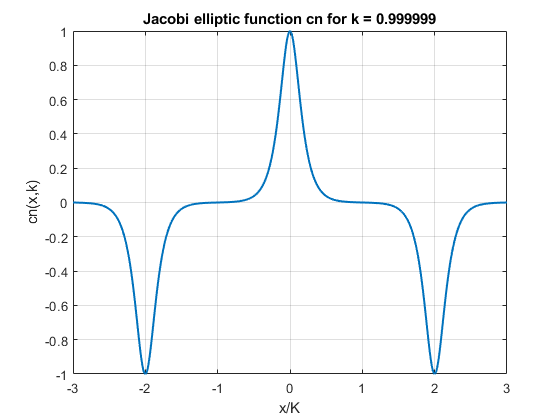

figure
x=-3:0.01:3;
k = 0.999999;
plot(x,JacobiCN(elK(k)*x,k),'LineWidth',1.5)
xlabel('x/K')
ylabel('cn(x,k)')
title(sprintf('Jacobi elliptic function cn for k = %g',k))
grid on

**Example 2**

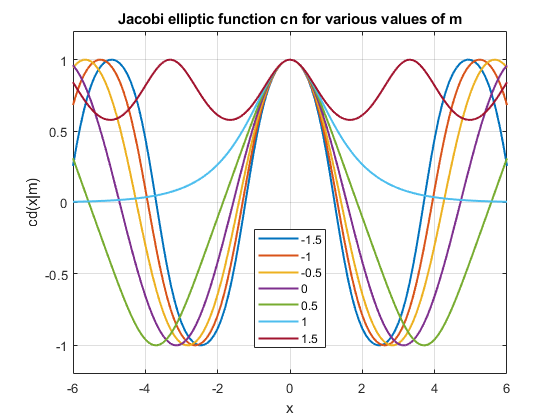

figure
X = -6:0.1:6;
M = -1.5:0.5:1.5;
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mJacobiCN(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) -1.2 1.2])
grid on
legend(clg,'Location','Best')
title('Jacobi elliptic function cn for various values of m')
xlabel('x')
ylabel('cd(x|m)')

**Example 3**

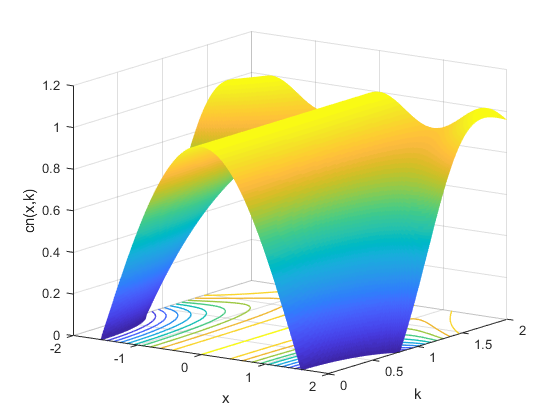

figure
x=-2:0.01:2;
k=0:0.01:2;
[X,K]=meshgrid(x,k);
hs=surfc(X,K,JacobiCN(X,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = 0;
hc.LineWidth = 1;
hc.LevelList = 0:0.1:1;
caxis([0 1])
view([35 15]);
xlabel('x')
ylabel('k')
zlabel('cn(x,k)')
zlim([0 1.2])
grid on

**Example 4**

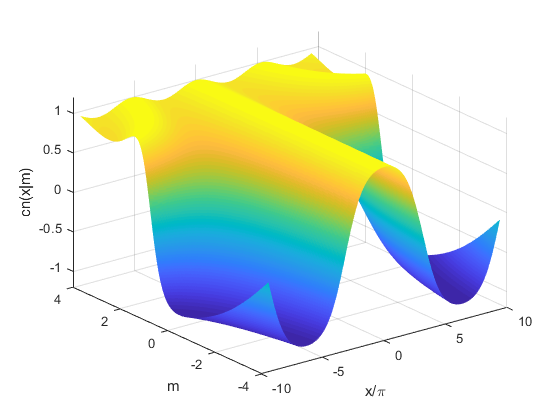

figure
x=-3:0.01:3;
m=-4:0.01:4;
[X,M]=meshgrid(x,m);
surface(pi*X,M,mJacobiCN(X,M),'EdgeColor','none')
view(3)
caxis([-1 1])
xlabel('x/\pi')
ylabel('m')
zlabel('cn(x|m)')
zlim([-1.2 1.2])
grid on

**Example 5**

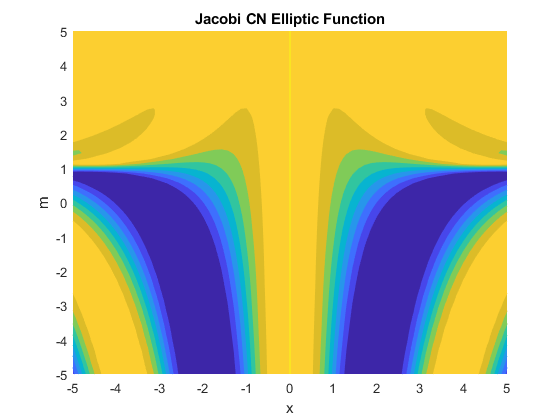

figure
f = @(x,m)mJacobiCN(x,m);
fcontour(f,'Fill','on')
title('Jacobi CN Elliptic Function')
xlabel('x')
ylabel('m')

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22)

[Jacobi elliptic functions, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

[1] R. Bulirsch, Numerical Calculation of Elliptic Integrals and Elliptic Functions. Numerische Mathematik 7, 78-90, 1965

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

## See Also